# HW2_1_6

First remove all open background.

close all;
clear;
clc;

define the Fs for showing signal correctly.

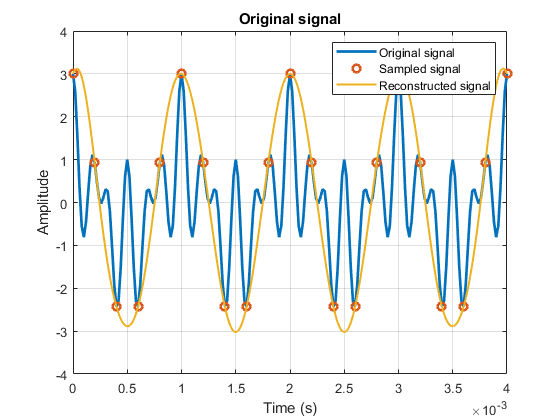

fs = 50000;
t = 0:1 / fs:0.004;
fc1 = 1000;
fc2 = 4000;
fc3 = 6000;
fs_low = 5000;
ts = 0:1 / fs_low:0.004;
x_original = cos(2 * pi * fc1 * t) + cos(2 * pi * fc2 * t) + cos(2 * pi * fc3 * t);
x_sampled = cos(2 * pi * fc1 * ts) + cos(2 * pi * fc2 * ts) + cos(2 * pi * fc3 * ts);
figure('Name', 'Aliasing in the time domain');
plot(t, x_original, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original signal');
grid on;
hold on;
plot(ts, x_sampled, 'o','LineWidth', 2);
legend('Original signal', 'Sampled signal');
prc_rate = 100;
t1 = 0.000:1 / (prc_rate * fs_low):4e-3;
t2 = -0.004:1 / (prc_rate * fs_low):4e-3;
x1 = zeros(1, length(t1));
x1(1:prc_rate:end) = x_sampled;
h = sinc(fs_low * t2);
y = conv(x1, h, 'same');
plot(t1, y, 'LineWidth', 1.5);
legend('Original signal', 'Sampled signal', 'Reconstructed signal')